# Wind jitter assessment using LTAO simulation data

The.

## Summary of the results

..

## Preamble

Load LOM data:

filename1 = fullfile(im.lfFolder,'ceo-data','lom_tt_dt.mat');
load(filename1,'D_seg_tt');
fprintf('\nTT sensitivity matrix loaded from \n%s\n',filename1);


TT sensitivity matrix loaded from 
/Users/rromano/Workspace/gmt-data/ceo-data/lom_tt_dt.mat


filename2 = fullfile(im.lfFolder,'ceo-data','D_seg_piston_dt.mat');
load(filename2,'D_seg_piston');
fprintf('Piston sensitivity matrix loaded from \n%s\n',filename2);

Piston sensitivity matrix loaded from 
/Users/rromano/Workspace/gmt-data/ceo-data/D_seg_piston_dt.mat


filename3 = fullfile(im.lfFolder,'ceo-data','rbm2gtt.mat');
load(filename3,'rbm2gtt');
fprintf('Global TT sensitivity matrix loaded from \n%s\n',filename3);

Global TT sensitivity matrix loaded from 
/Users/rromano/Workspace/gmt-data/ceo-data/rbm2gtt.mat


Ts = 1/8e3;     % Simulation sampling period

## Load simulation data

if false
    dt_filename = "zen30az000_OS7_ltao_test_%sESFF_noWLoffset.mat"; %#ok<*UNRCH> 
else, dt_filename = "zen30az000_OS7_ltao_test_%sESFF.mat";
end

load(sprintf(dt_filename,"no"),"m1rbm_dt","m2rbm_dt");
t = 0:Ts:(size(m1rbm_dt,1)-1)*Ts;
stt1 = D_seg_tt*[m1rbm_dt,m2rbm_dt]';
gtt1 = rbm2gtt*[m1rbm_dt,m2rbm_dt]';
m2stt1 = D_seg_tt(:,43:84)* m2rbm_dt';
stt_wo_gtt1 = (eye(14) - kron(eye(2),kron(ones(7),1/7))) * stt1;
sp1 = D_seg_piston*[m1rbm_dt,m2rbm_dt]';
sdp1 = sp1 - sp1(7,:);

load(sprintf(dt_filename,"m1"),"m1rbm_dt","m2rbm_dt");
stt2 = D_seg_tt*[m1rbm_dt,m2rbm_dt]';
gtt2 = rbm2gtt*[m1rbm_dt,m2rbm_dt]';
m2stt2 = D_seg_tt(:,43:84)* m2rbm_dt';
stt_wo_gtt2 = (eye(14) - kron(eye(2),kron(ones(7),1/7))) * stt2;
sp2 = D_seg_piston*[m1rbm_dt,m2rbm_dt]';
sdp2 = sp2 - sp2(7,:);

load(sprintf(dt_filename,"m1m2"),"m1rbm_dt","m2rbm_dt");
stt3 = D_seg_tt*[m1rbm_dt,m2rbm_dt]';
gtt3 = rbm2gtt*[m1rbm_dt,m2rbm_dt]';
m2stt3 = D_seg_tt(:,43:84)* m2rbm_dt';
stt_wo_gtt3 = (eye(14) - kron(eye(2),kron(ones(7),1/7))) * stt3;
sp3 = D_seg_piston*[m1rbm_dt,m2rbm_dt]';
sdp3 = sp3 - sp3(7,:);

## Results

### Differential segment piston RMS plot

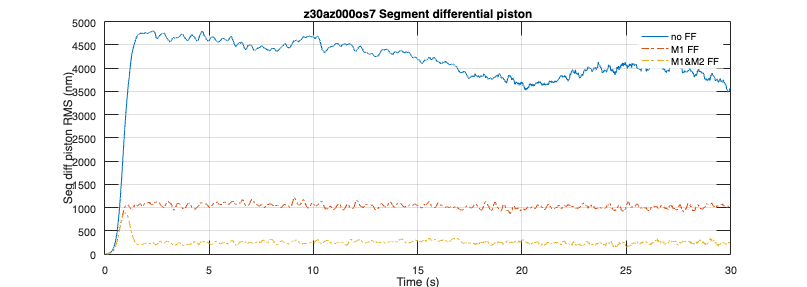

figure; set(gcf,'Position',[833   323   900   320]);%360   277   560   420
subplot(111)
sdp1_rms = 1e9*sqrt(mean(sdp1.^2,1));
sdp2_rms = 1e9*sqrt(mean(sdp2.^2,1));
sdp3_rms = 1e9*sqrt(mean(sdp3.^2,1));
plot(t,sdp1_rms,'-',t,sdp2_rms,'-.',t,sdp3_rms,'-.');
set(gca,'Fontsize',12);
grid on;
title('z30az000os7 Segment differential piston')
xlabel('Time (s)'); ylabel('Seg diff piston RMS (nm)');
legend('no FF','M1 FF','M1&M2 FF'); legend box off;

In AdOptica's phasing report (ADP_GASM-190-01_ANR_v4), the piston phasing error criteria is


$$SPP = \frac{1}{N} \sum_{k=1}^N \sigma_p[k] ,$$


where $\sigma_p[k]$ is the standard deviation of the differential segment piston $\delta p$ at instant $k$, i.e.


$$\sigma_p[k] = \text{std}\left( \delta p_i[k] \right) = \sqrt{\frac{1}{7} \left[ \sum_{i=1}^7 \left(\delta p_i[k] - \bar{\delta p}[k] \right)^2\right]}$$


and $\bar{\delta p}[k] = \frac{1}{7} \sum_{i=1}^7 \delta p_i[k]$.

wstd=1;
fprintf('%s\n no FF:%.3gnm\n M1 FF:%.3gnm\n M1&M2 FF:%.3gnm\n',...
    "Mean (over time) of the Seg Diff piston STD:",...
    1e9*mean(std(sdp1,wstd,1)),1e9*mean(std(sdp2,wstd,1)),1e9*mean(std(sdp3,wstd,1)));

Mean (over time) of the Seg Diff piston STD:
 no FF:1.66e+03nm
 M1 FF:985nm
 M1&M2 FF:203nm
